Si vuole comprimere l'immagine house.y (512 x 512, uint8) usando la DCT su blocchi di 64 pixel, ma aventi diversi rapporti d'aspetto. A tal fine, scrivete una funzione function y = codec(x,K,L) in cui calcolate la DCT di blocchi K x L dell'immagine x, conservate solo gli 8 coeffcienti piu grandi (in modulo) di ogni blocco, li sottoponete a quantizzazione uniforme con passo 16, e infine ricostruite l'immagine y a partire dai blocchi quantizzati. Nello script ex2.m realizzate un esperimento in cui, per ognuna delle seguenti dimensioni del blocco: 8x8, 4x16, 2x32, 1x64, effettuate la compressione di house.y e valutate l'MSE rispetto all'immagine originale.

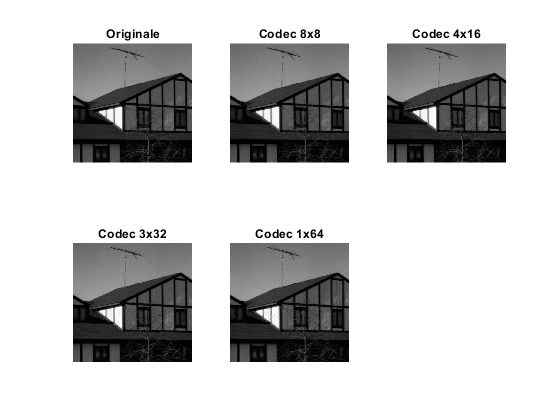

close all; clear all; clc;
fid = fopen('house.y','rb');
x = fread(fid,[512 512],'uint8');
x = x';
fclose(fid);

% Codec
y(:,:,1) = codec(x,8,8);
y(:,:,2) = codec(x,4,16);
y(:,:,3) = codec(x,2,32);
y(:,:,4) = codec(x,1,64);

% MSE
for i=1:4
    MSE(i) = mean2((x-y(:,:,i)).^2);
end

% Visualizzazione
figure;
subplot(231); imshow(x,[0 255]); title('Originale');
subplot(232); imshow(y(:,:,1),[0 255]); title('Codec 8x8');
subplot(233); imshow(y(:,:,2),[0 255]); title('Codec 4x16');
subplot(234); imshow(y(:,:,3),[0 255]); title('Codec 3x32');
subplot(235); imshow(y(:,:,4),[0 255]); title('Codec 1x64');

function y = codec(x,K,L)

    % DCT custom
    xdct = blkproc(x,[K L],@dctcustom);
    
    % Quantizzazione uniforme
    xmax = max(xdct(:));  xmin = min(xdct(:));
    delta = 16;
    xq = delta*(round(xdct/delta));
    
    % Antitrasformata
    y = blkproc(xq,[K L],@idct2);
    
end

function y = dctcustom(x)
    
    % Conservati solo 8 coefficienti più grandi in modulo
    xdct = dct2(x);
    [~,index] = sort(abs(xdct(:)));
    y = xdct;
    y(index(1:end-8)) = 0;
    
end